# Stanford BPSM PM Toolbox Workshop

**Mustafa Al Ibrahim (Mustafa.Geoscientist@outlook.com)**

**Version: 19.01.23 **

## Introduction

Welcome to this quick tutorial on running the Stanford BPSM PetroMod toolbox. In this tutorial, we will do two activities. The first one   will focus on building the workflow suggested in the presentation which follows the process below. The second one will focus on a simple example where we will change the structure of a 2D model. The workflow followed

- Create the template model in PetroMod.

- sample the paramters that will be changing.

- Update/create lithologies. Create updte models

- Simulate the models (in parrallel if desired)

- Load data into matlab. Save the data in Matlab if needed.

- Use the results in Matlab

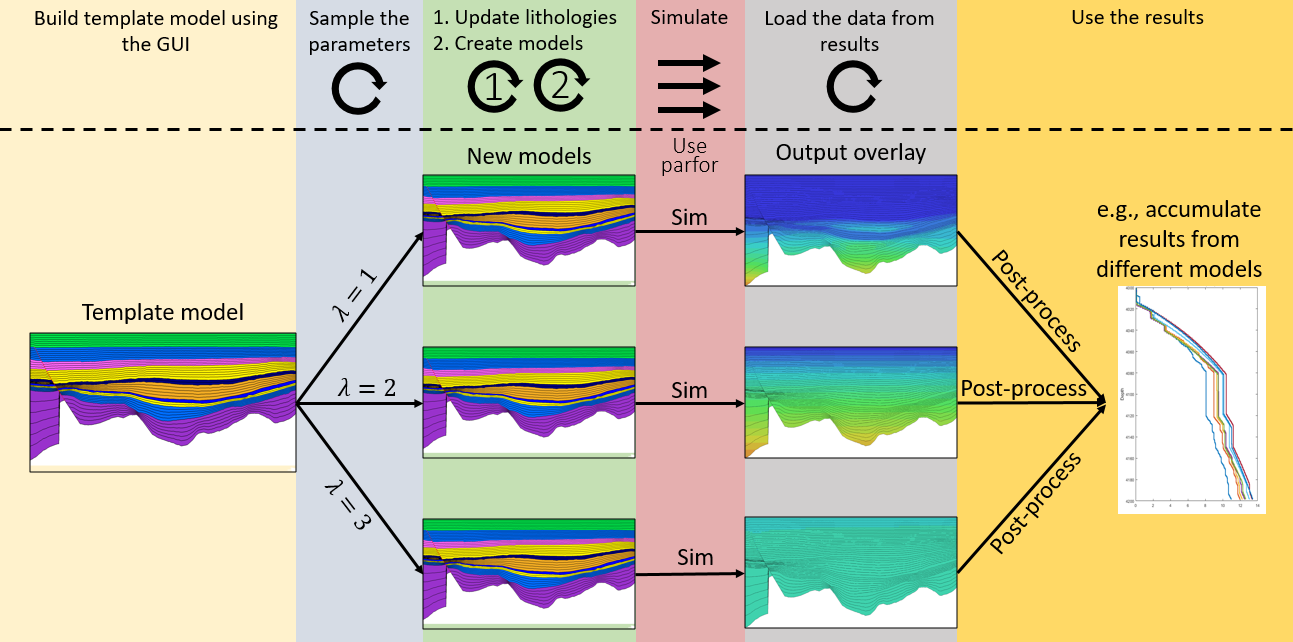

## 1. Create the template model in PetroMod

We have provided a PetroMod 2017 project with a two models, one 1D and one 2D. In most of the tutorial, we will use the 1D example below. We are interested in F18 in

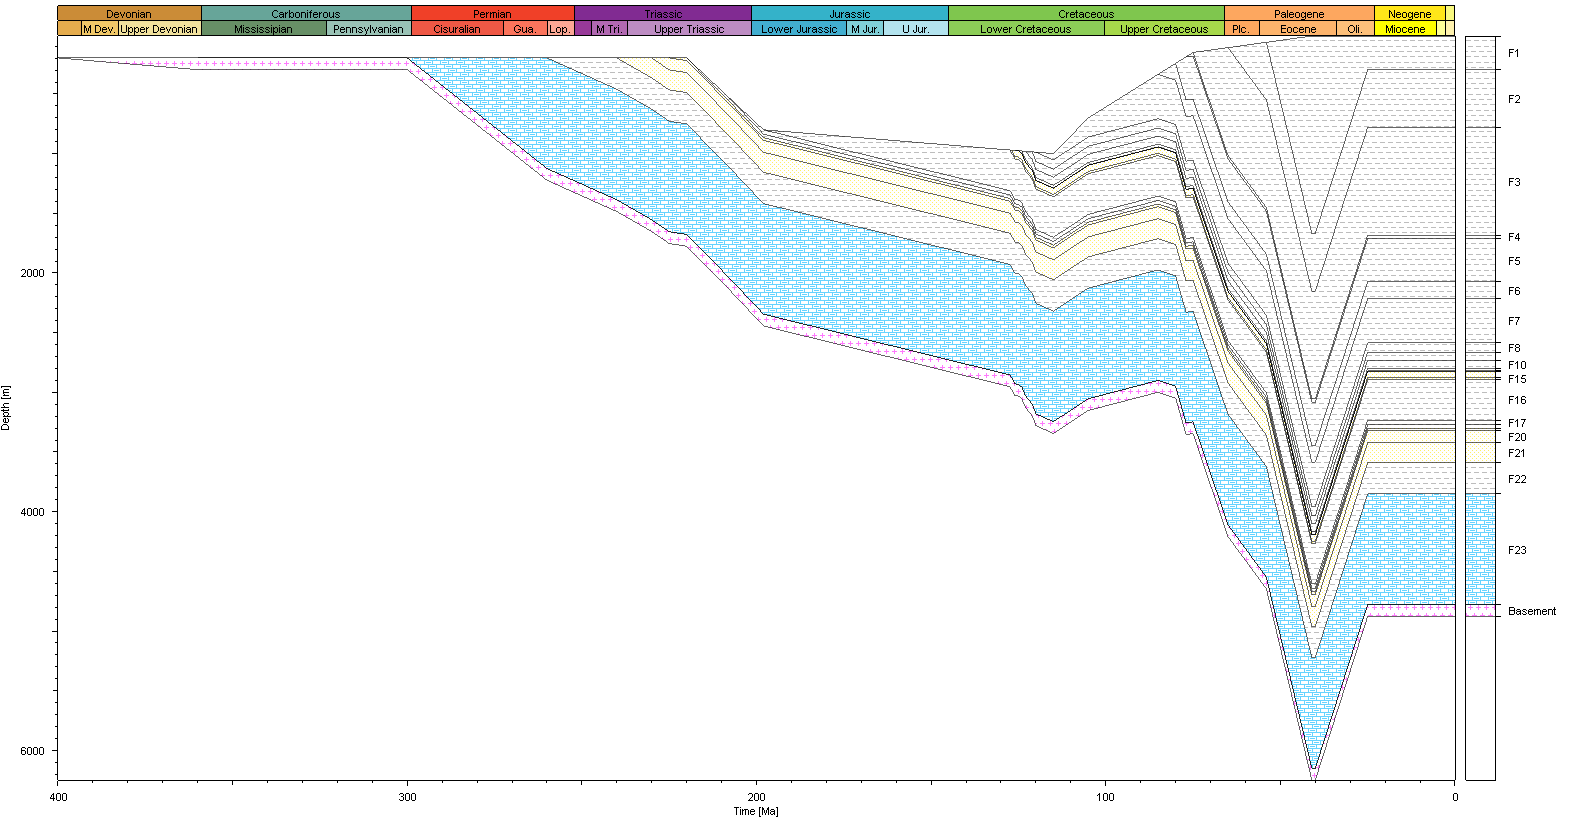

## 2. Sample the parameters

We are not sure about three things in our main studied interval. In

- F16: the sand proportion mixed with the shale is between 0-40% following uniform distribution

- F17: the density is uncertain with a gaussian of mean 2700 and standord deviation of 100 kg/m3.

- F18: the TOC is uncertain with a lognormal distribution with mean of 5, and variance of 2 wt%

We will have 10 models. Note that 10 is too small for statistical purposes but this is just a tutorial. First. Let us build the variables. Note that the variables sampled are not correlated, we can sample each of them independently.

% Number of models 
nModels = 10;  

% Sample from uniform distrubtion for F16
F16_sandProp  = rand(nModels,1)*.4;

% Sample from normal (gaussian) distribution truncated from the left
F17_rho = normrnd(2700, 100, [nModels,1]);

% Sample from normal (gaussian) distribution truncated from the left
m = 5;
v = 2;
mu = log((m^2)/sqrt(v+m^2));
sigma = sqrt(log(v/(m^2)+1));
F18_toc = lognrnd(mu,sigma,[nModels,1]);
F18_toc(F18_toc<0) = 0;

## 3.1 Update the lithology

It is good practice to create all the used lithologies first before creating the models. This is because saving the lithology file takes time (on the order of 10s of seconds). 

Also, it is better to create new lithology for each model, rather than update the lithology in real time and simulating the current model. By creating a lithology for each model (and not referencing one lithology for all of them), you will ensure that simulating the models in the future will produce the correct result.

Note that we only need to create lithologies for F16 and F17. F18 TOC is updated in the main table. Let's create the lithologies. First, let us load the project.

% Define PetroMod direc (NEED TO BE UPDATED TO MATCH YOUR PC LOCATION)
PMDirectory = 'C:\Program Files\Schlumberger\PetroMod 2017.1\WIN64\bin';
PMProjectDirectory = 'C:\Users\malibrah\Documents\GitHub\PMToolbox\Workshop\PM17 Workshop Project';

% Open the project
PM = PetroMod(PMDirectory, PMProjectDirectory);

Now we are going to load the lithology file. This might take some time (10s of seconds).

PM.loadLithology();

Now, that we loaded the lithology file, we can obtain all kinds of information about lithologies. Here are some examples. these lines of code are not part of our main goal. Note in particular, the getLithologyId, this id will be inputted to the main table.

lithoInfo = PM.Litho.getLithologyInfo('Shale (typical)');
[PetroModId, id]   = PM.Litho.getLithologyId('Shale (typical)');
athysFactor = PM.Litho.getValue('Sandstone (clay rich)', 'Athy''s Factor k (depth)');
heatCapacityCurve = PM.Litho.getValue('Sandstone (clay rich)', 'Heat Capacity Curve');

Anyway, let's go back to our main goal which is to create lithologies for our project. First. Let's create lithologies for F16. We need to create mixtures. Here is how to do it:

% create the mixer and define the source lithologies
mixer = LithoMixer('V');    % V for layerd and H for homogeneous 
sourceLithologies = {'Sandstone (typical)','Shale (typical)'};

F16_Ids = [];
for i = 1:nModels
    
    % Define a new name for the lithology
    lithoName = ['F16_Model_' num2str(i)];

    % Get the fractions of sand and shale
    fractions  = [F16_sandProp(i), 1-F16_sandProp(i)];
    
    % Mix the lithologies and move the lithology into its own folder for organization purposes
    PM.Litho.mixLitholgies(sourceLithologies, fractions, lithoName , mixer);
    PM.Litho.changeLithologyGroup(lithoName, 'Workshop', 'F16')
    
    % Store the id for later use (updated to take care of version issues)
    if PM.version >=2018
        [~, F16_Ids(i)]   = PM.Litho.getLithologyId(lithoName);
    else
        [F16_Ids(i),~]   = PM.Litho.getLithologyId(lithoName);
    end

end

Now we create the lithologies for F17. This is easier. We will copy the shale typical and then update its properites.

F17_Ids = [];
for i = 1:nModels
    
    % Define a new name for the lithology
    lithoName = ['F17_Model_' num2str(i)];

    % Duplicate the lithology, and move it to the specified folder and subfolder
    PM.Litho.duplicateLithology('Shale (organic rich, 3% TOC)', lithoName, 'Workshop', 'F17');
    
    % Update the thermal conductivity
    PM.Litho.changeValue(lithoName, 'Density' , F17_rho(i));
    
    % Store the id for later use
    F17_Ids(i)   = PM.Litho.getLithologyId(lithoName);
end

 Finally, we need to save the Lithology back to the file

PM.saveLithology();

Note that if you need to delete a lithology, you can use this. we will not use this. You can also restore the backed up lithology file.

% PM.Litho.deleteLithology('LithologyToBeDeleted');
% PM.restoreProject();

## 3.2 Create the models

We are now ready to create the models and modify them accordingly. Remember that F18 needs adjusting in each model. Let's first examine the template model to determine what needs adjusting.

templateModel = 'Workshop1D';
nDim = 1;
model = Model1D(templateModel, PMProjectDirectory);

% Get available tables and print one of them
model.getTableNames();

% Get the data and put the data back (you can modify the data before putting it back)
data = model.getData('Heat Flow');
model.updateData('Heat Flow', data);

% Get the main table
model.printTable('Main');

c
c Main1d data [PetroMod 2017.1]
c
Head   | Top ID |   Age    |      Name       |      Depth      |      Thickness      | Event type |      Name       | Paleodeposition/ | Paleodeposition/ | Lithology | PSE |               Kinetic                |    TOC     |     HI      | Color Layer | Color Facies | Tool Usage | Thrusting start age |
Head   |        |   [Ma]   |  top/well pick  |       [m]       |         [m]         |            |   layer/event   |     erosion      | erosion balance  |           |     |                                      |    [%]     | [mgHC/gTOC] |             |              |            |        [Ma]         |
Head   |        |          |                 |                 |                     |            |                 |       [m]        |       [m]        |           |     |                                      |            |             |             |              |            |                     |
Key    | TopID  |  TopAge  |     TopName     | Prese

Ok, now we know the TOC is in cell (21, 13). You can do more complicated ways to find it such as searching for F18 in the name column, but for simplicity, we will just hard code it directly. We will now dublicate the model and and modify the new dublicated models with the new lithologies and TOC.

for i = 1:nModels
    
    % New model name 
    newModel = ['Model_' num2str(i)];
    
    disp(['Creating ' newModel]);
    
    % Duplicate model
    PM.duplicateModel(templateModel, newModel, nDim);
    
    % Load the new model and table
    model = Model1D(newModel, PMProjectDirectory);
    
    % Modify the table (TOC, two lithologies)... note that it is a cell array
    data = model.getData('Main');
    data{19,10} = F16_Ids(i);
    data{20,10} = F17_Ids(i);
    data{21,13} = F18_toc(i);
    model.updateData('Main', data);
    
    % Save the update 
    model.updateModel();
    
end

Creating Model_1
Creating Model_2
Creating Model_3
Creating Model_4
Creating Model_5
Creating Model_6
Creating Model_7
Creating Model_8
Creating Model_9
Creating Model_10


Note that if you need to delete a model, you can use this. we will not use this.

nDim = 1; % Number of dimensions
PM.deleteModel('ModelToDelete', nDim);

## 4. Simulation

Now we are ready to run the simulations.

for i = 1:nModels
    
    % New model name 
    newModel = ['Model_' num2str(i)];
    
    disp(['Simulating ' newModel]);
    
    % Simulate
    [output] = PM.simModel(newModel, nDim, false);
    
end

Simulating Model_1
Simulating Model_2
Simulating Model_3
Simulating Model_4
Simulating Model_5
Simulating Model_6
Simulating Model_7
Simulating Model_8
Simulating Model_9
Simulating Model_10


## 5. Post-process

Now we need to post process the results. We will use open simulator. Right now, we are restricted to demo scripts. But in general, you can run any script written for open simulator using the command below.

% Run a DEMO script on the output
[cmdout, status] = PM.runScript(newModel, nDim, 'demo_opensim_output_3rd_party_format', '4', false);

For now, we will use ''demo_opensim_output_3rd_party_format" script to retrieve some output layers at present day. We have a special functions for this script to make things simpler. First, we need the layer numbers that we want to retrieve. This could change from project to project depending on what are you outputting. So make sure that all your models are outputting the same things.

[cmdout] = getAvailableOverlays(newModel, nDim, PM)

cmdout =     'This program includes 3rd-party Python software which is subject to the following:
     Copyright (c) 2001-2015 Python Software Foundation; All Rights Reserved
     and additional restrictions; to display full copyright and license information for the Python software use the option --pylicense
     
     Initializing PetroMod Res() from args and environment...
     Setting project and model paths from Res()...
     Project: C:/Users/malibrah/Documents/GitHub/PMToolbox/Workshop/PM17 Workshop Project/
     Model:   C:/Users/malibrah/Documents/GitHub/PMToolbox/Workshop/PM17 Workshop Project/pm1d/Model_1
     Out dir: C:/Users/malibrah/Documents/GitHub/PMToolbox/Workshop/PM17 Workshop Project/pm1d/Model_1/out/
     Initializing interpreter...
     
     Execute script: C:/Program Files/Schlumberger/PetroMod 2017.1/scripts/demo_opensim_output_3rd_party_format.py
     with arguments: 100000 
     Loaded module pmio.
     Loaded module pmpy.
     PetroMod project path is C:/User

Now that we have the overlays that we want, [7, 18, 16], we can retrieve them for all of our models

% overlayNumbers = [7,18, 16];
% [data, layerNames] = loadOutputOverlays(newModel, nDim, PM, overlayNumbers);

Ok. That works, let's run it for each model.

nDim = 1;
overlayNumbers = [7,18,16];
data = [];
for i = 1:nModels
    
    newModel = ['Model_' num2str(i)];
    disp(['Loading output for ' newModel]); 
    [data(:,:,i), layerNames] = loadOutputOverlays(newModel, nDim, PM, overlayNumbers);
    
end

Loading output for Model_1
Loading output for Model_2
Loading output for Model_3
Loading output for Model_4
Loading output for Model_5
Loading output for Model_6
Loading output for Model_7
Loading output for Model_8
Loading output for Model_9
Loading output for Model_10


## 6. Do whatever you want with the output

Plot the outputs. Note that depth is the base of each layer, not the top so we had to subtract the base to obtain the tops.

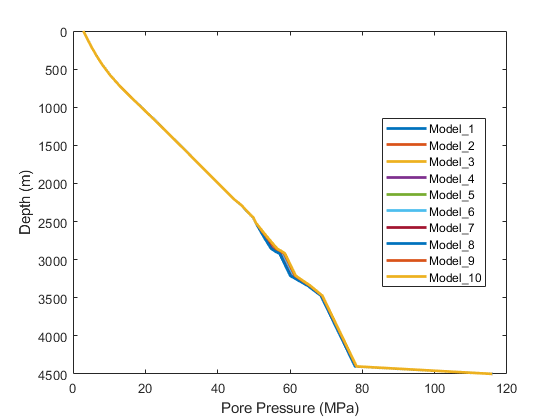

iToPlot = 2;
figure('Color', 'White');
legendText= [];
for i=1:nModels
   legendText{i} = ['Model_' num2str(i)];
   plot(data(:,iToPlot,i), data(:,1,i)-data(end,1,i),'LineWidth',2); hold on
end
set(gca, 'yDir', 'reverse')
xlabel('Pore Pressure (MPa)')
ylabel('Depth (m)')
legend(legendText, 'Location','Best', 'Interpreter','none')

## Summary

Here is the whole workflow in one go

% PART 1: Define your parameters

% Number of models 
nModels = 10;  

% Sample from uniform distrubtion for F16
F16_sandProp  = rand(nModels,1)*.4;

% Sample from normal (gaussian) distribution truncated from the left
F17_rho = normrnd(2700, 100, [nModels,1]);

% Sample from normal (gaussian) distribution truncated from the left
m = 5;
v = 2;
mu = log((m^2)/sqrt(v+m^2));
sigma = sqrt(log(v/(m^2)+1));
F18_toc = lognrnd(mu,sigma,[nModels,1]);
F18_toc(F18_toc<0) = 0;

% ================================================================================

ans = 1×21 cell array
    {'Facies'}    {'Fault'}    {'Grid'}    {'Heat Flow Group'}    {'Heat Flow Map'}    {'Heat Flow Table'}    {'Heat Flow Trend'}    {'Layers'}    {'Mckenzie'}    {'Paleo Water Group'}    {'Paleo Water Map'}    {'Paleo Water Table'}    {'Paleo Water Trend'}    {'Rift'}    {'SWIT Group'}    {'SWIT Map'}    {'SWIT Table'}    {'SWIT Trend'}    {'TS 1 B 1 Depth'}    {'TS 1 B 1 Facies'}    {'Tools'}


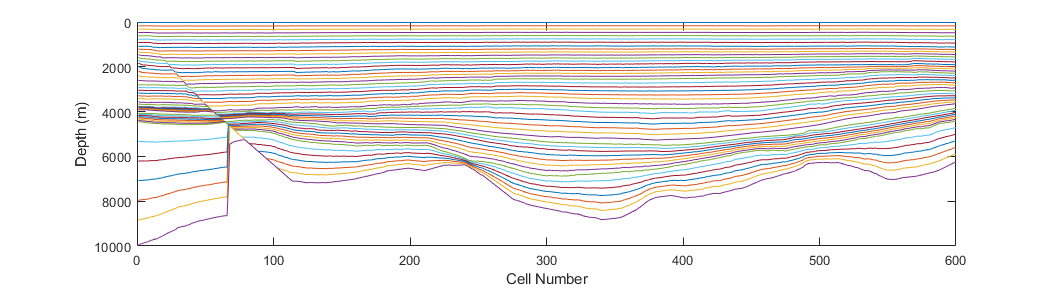

% Part 3.1: Create lithologies

% Define PetroMod direc (NEED TO BE UPDATED TO MATCH YOUR PC LOCATION)
PMDirectory = 'C:\Program Files\Schlumberger\PetroMod 2017.1\WIN64\bin';
PMProjectDirectory = 'C:\Users\malibrah\Documents\GitHub\PMToolbox\Workshop\PM17 Workshop Project';


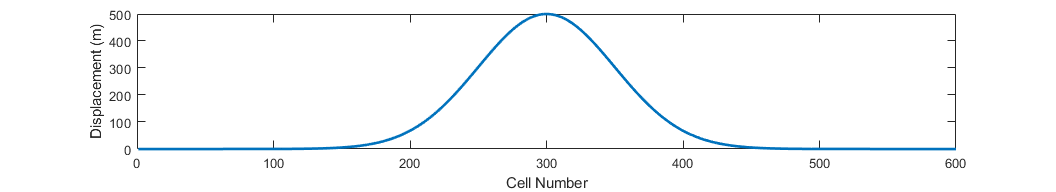

% Open the project and load lithology
PM = PetroMod(PMDirectory, PMProjectDirectory);
PM.loadLithology();

% create the mixer and define the source lithologies
mixer = LithoMixer('V');    % V for layerd and H for homogeneous 
sourceLithologies = {'Sandstone (typical)','Shale (typical)'};


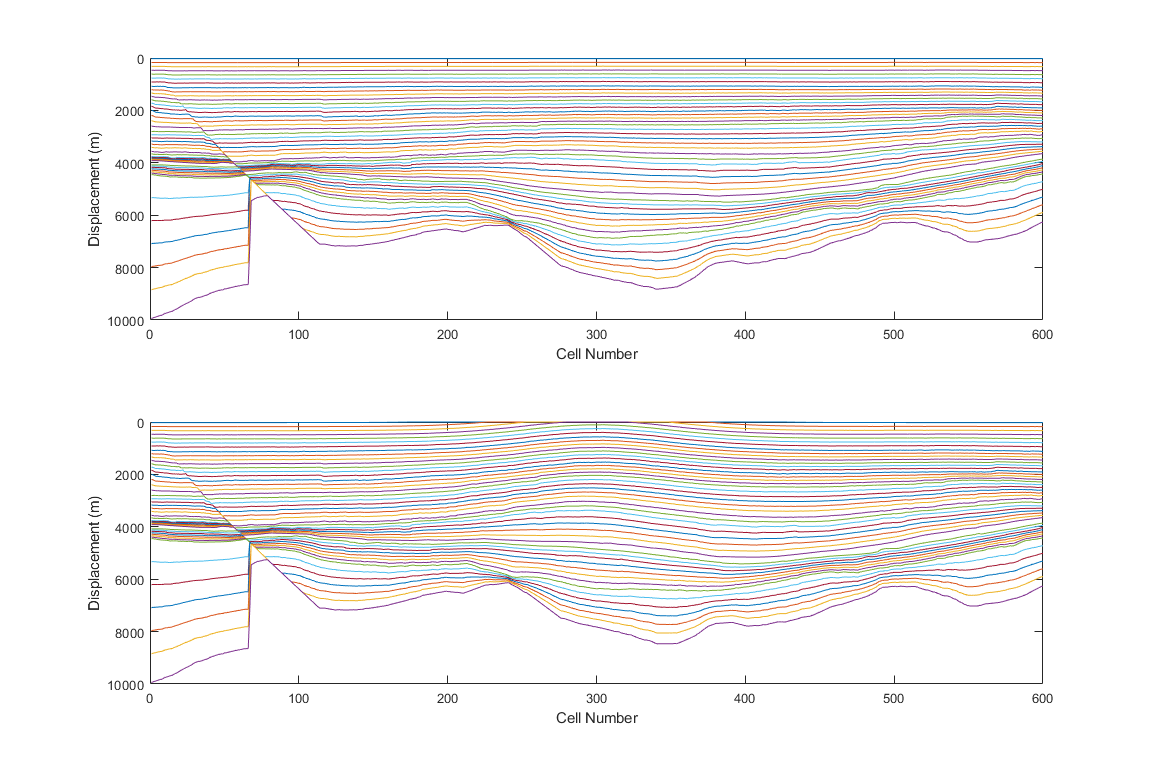

F16_Ids = [];
for i = 1:nModels
    
    % Define a new name for the lithology
    lithoName = ['F16_Model_' num2str(i)];

    % Get the fractions of sand and shale
    fractions  = [F16_sandProp(i), 1-F16_sandProp(i)];
    
    % Mix the lithologies and move the lithology into its own folder for organization purposes
    PM.Litho.mixLitholgies(sourceLithologies, fractions, lithoName , mixer);
    PM.Litho.changeLithologyGroup(lithoName, 'Workshop', 'F16')

    
    % Store the id for later use
    F16_Ids(i)   = PM.Litho.getLithologyId(lithoName);
end

F17_Ids = [];
for i = 1:nModels
    
    % Define a new name for the lithology
    lithoName = ['F17_Model_' num2str(i)];

    % Dublicate the lithology, and move it to the specified folder and subfolder
    PM.Litho.duplicateLithology('Shale (organic rich, 3% TOC)', lithoName, 'Workshop', 'F17');
    
    % Update the thermal conductivity
    PM.Litho.changeValue(lithoName, 'Density' , F17_rho(i));
    
    % Store the id for later use
    F17_Ids(i)   = PM.Litho.getLithologyId(lithoName);
end

PM.saveLithology();

% ================================================================================
% Part 3.2: Create models

% Number of dimensions in the model
nDim = 1;

% Our source model
templateModel = 'Workshop1D';

for i = 1:nModels
    
    newModel = ['Model_' num2str(i)];    
    disp(['Creating ' newModel]);
    
    % Duplicate model
    PM.duplicateModel(templateModel, newModel, nDim);
    
    % Load the new model and table
    model = Model1D(newModel, PMProjectDirectory);
    
    % Modify the table (TOC, two lithologies)... note that it is a cell array
    data = model.getData('Main');
    data{19,10} = F16_Ids(i);
    data{20,10} = F17_Ids(i);
    data{21,13} = F18_toc(i);
    model.updateData('Main', data);
    
    % Save the update 
    model.updateModel();
    
end

% ================================================================================
% Part 4: Simulate models

for i = 1:nModels
    
    newModel = ['Model_' num2str(i)];
    disp(['Simulating ' newModel]);
    
    % Simulate
    [output] = PM.simModel(newModel, nDim, false);
    
end

% ================================================================================
% Part 5: Read the output

[cmdout] = getAvailableOverlays(newModel, nDim, PM)
overlayNumbers = [7,18, 16];

data = [];
for i = 1:nModels
    
    newModel = ['Model_' num2str(i)];
    disp(['Loading output for ' newModel]); 
    [data(:,:,i), layerNames] = loadOutputOverlays(newModel, nDim, PM, overlayNumbers);
    
end

% ================================================================================
% Part 6: Plot the output

iToPlot = 2;
figure('Color', 'White');
legendText= [];
for i=1:nModels
   legendText{i} = ['Model_' num2str(i)];
   plot(data(:,iToPlot,i), data(:,1,i)-data(end,1,i),'LineWidth',2); hold on
end
set(gca, 'yDir', 'reverse')
xlabel('Pore Pressure (MPa)')
ylabel('Depth (m)')
legend(legendText, 'Location','Best', 'Interpreter','none')


## Extra

We will quickly show how to modify structure in a 2D model. The 2D model is provided curtasy of of Anshuman Pradhan. In this exercise, we will load a 3D model, duplicate it, modify the structure. The code is bare minimum.

% Define parameters
PMDirectory = 'C:\Program Files\Schlumberger\PetroMod 2017.1\WIN64\bin';
PMProjectDirectory = 'C:\Users\malibrah\Documents\GitHub\PMToolbox\Workshop\PM17 Workshop Project';
templateModel = 'Structural2D';
newModel      = 'Structural2DModified';
nDim = 2;

% Load the project
PM = PetroMod(PMDirectory, PMProjectDirectory);

% Duplicate the model
PM.duplicateModel(templateModel, newModel, nDim);
    
% Load the new model and table
model = Model2D(newModel, PMProjectDirectory);

% Get the tables just to see if we have data
model.getTableNames()

% Note that the structural data are stored in 'TS 1 B 1 Depth'
data = model.getData('TS 1 B 1 Depth');
figure('Color', 'White', 'Units','inches', 'Position',[3 3 11 3],'PaperPositionMode','auto');
plot(1:size(data,2), data); xlabel('Cell Number'); ylabel('Depth (m)')
set(gca,'yDir', 'Reverse')

% 600 x points, 46 horizons. We can do whatever we want with it. We will add a simple anticline between x = 400,500
x = 1:600;
maxY = 500;
y = normpdf(x,300,50);
y = y*(maxY/max(y));
figure('Color', 'White', 'Units','inches', 'Position',[3 3 11 2],'PaperPositionMode','auto');
plot(x,y, 'LineWidth',2); xlabel('Cell Number'); ylabel('Displacement (m)')
% We will add this function to all the layers and erode the top
dataWithAnticline = data - y;               % Note use broadcasting (matrix + row = matrix + repmat(row) = matrix)
dataWithAnticline(dataWithAnticline<0) = 0; % Erode the top

% Update the model
figure('Color', 'White', 'Units','inches', 'Position',[2 2 12 8],'PaperPositionMode','auto');
subplot(2,1,1)
plot(1:size(data,2), data)
set(gca,'yDir', 'Reverse'); xlabel('Cell Number'); ylabel('Displacement (m)')
subplot(2,1,2)
plot(1:size(dataWithAnticline,2), dataWithAnticline)
set(gca,'yDir', 'Reverse'); xlabel('Cell Number'); ylabel('Displacement (m)')
% Put the new data into the model and save it
model.updateData('TS 1 B 1 Depth', dataWithAnticline);

% Save the update 
model.updateModel();